1

mc=1.5 %model parameters

mc = 1.5000

mp=0.5

mp = 0.5000

g=9.82

g = 9.8200

L=1

L = 1

d1=0.01

d1 = 0.0100

d2=0.01

d2 = 0.0100

A=[0,0,1,0;0,0,0,1;0,g*mp/mc,-d1/mc,-d2/(L*mc);0,g*(mp+mc)/(L*mc),-d1/(L*mc),-d2*(mc+mp)/(L*L*mc*mp)] %state matrices

A =          0         0    1.0000         0
         0         0         0    1.0000
         0    3.2733   -0.0067   -0.0067
         0   13.0933   -0.0067   -0.0267


B=[0;0;1/mc;1/(L*mc)]

B =          0
         0
    0.6667
    0.6667


C1=[1,0,0,0]

C1 =      1     0     0     0


C2=[0,1,0,0]

C2 =      0     1     0     0


D=0

D = 0

sys1=ss(A,B,C1,D) %creates state-space model

sys1 =
 
  A = 
              x1         x2         x3         x4
   x1          0          0          1          0
   x2          0          0          0          1
   x3          0      3.273  -0.006667  -0.006667
   x4          0      13.09  -0.006667   -0.02667
 
  B = 
           u1
   x1       0
   x2       0
   x3  0.6667
   x4  0.6667
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



sys2=ss(A,B,C2,D)

sys2 =
 
  A = 
              x1         x2         x3         x4
   x1          0          0          1          0
   x2          0          0          0          1
   x3          0      3.273  -0.006667  -0.006667
   x4          0      13.09  -0.006667   -0.02667
 
  B = 
           u1
   x1       0
   x2       0
   x3  0.6667
   x4  0.6667
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



2

P1=pole(sys1)

P1 =          0
   -3.6327
    3.6043
   -0.0050


P2=pole(sys2)

P2 =    -3.6327
    3.6043
   -0.0050
         0


e=eig(A)

e =          0
   -3.6327
    3.6043
   -0.0050


[z1,gain1]=zero(sys1)

z1 =     3.1237
   -3.1437


gain1 = 0.6667

[z2,gain2]=zero(sys2)

z2 = 	1.0e+-16 *

    0.2933
         0


gain2 = 0.6667

s1=isstable(sys1) %if s1=1, system is stable, else not

s1 = logical
   0


s2=isstable(sys2)

s2 = logical
   0


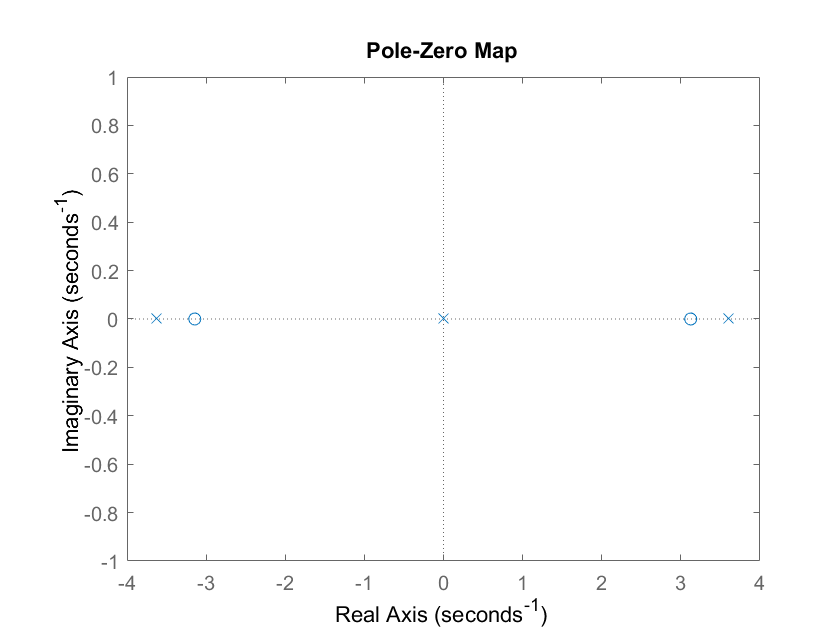

pzmap(sys1) %plots the zero pole map of the system

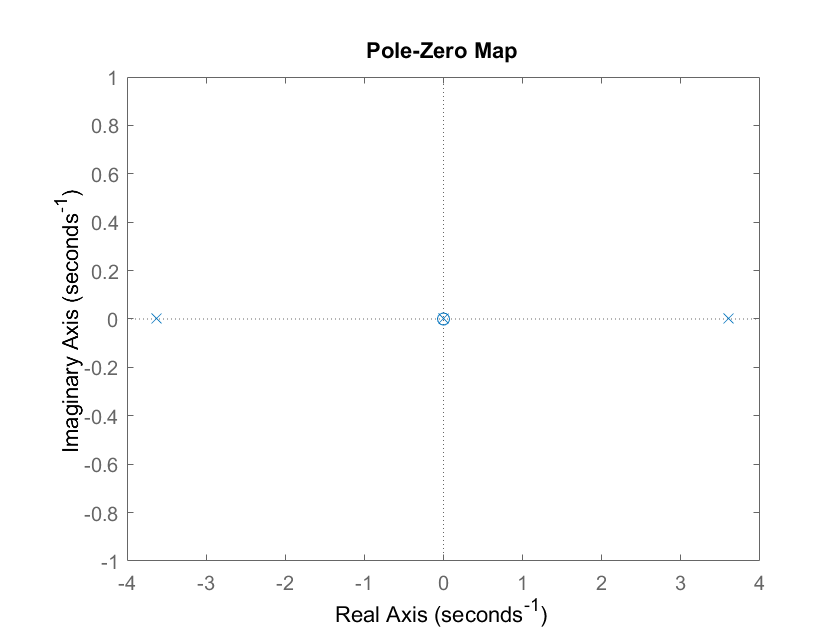

pzmap(sys2)

o1=rank(obsv(sys1)) %if o1=4 system is obseravble, else not

o1 = 4

o2=rank(obsv(sys2))

o2 = 3

c1=rank(ctrb(sys1)) %if c1=4 system is controllable, else not

c1 = 4

c2=rank(ctrb(sys2))

c2 = 4

3

sys1_tf=tf(sys1) %converts state-space model to transfer function

sys1_tf =
 
       0.6667 s^2 + 0.01333 s - 6.547
  -----------------------------------------
  s^4 + 0.03333 s^3 - 13.09 s^2 - 0.06547 s
 
Continuous-time transfer function.



sys2_tf=tf(sys2)

sys2_tf =
 
          0.6667 s - 1.956e-17
  -------------------------------------
  s^3 + 0.03333 s^2 - 13.09 s - 0.06547
 
Continuous-time transfer function.



[b1,a1]=ss2tf(A,B,C1,D) %converts state-space model to transfer function

b1 =          0         0    0.6667    0.0133   -6.5467


a1 =     1.0000    0.0333  -13.0932   -0.0655         0


[b2,a2]=ss2tf(A,B,C2,D)

b2 =          0         0    0.6667    0.0000    0.0000


a2 =     1.0000    0.0333  -13.0932   -0.0655         0


sys1_zpg=zpk(sys1) %converts to zero-pole-gain model

sys1_zpg =
 
    0.66667 (s-3.124) (s+3.144)
  -------------------------------
  s (s+3.633) (s-3.604) (s+0.005)
 
Continuous-time zero/pole/gain model.



sys2_zpg=zpk(sys2)

sys2_zpg =
 
            0.66667 s
  -----------------------------
  (s+3.633) (s-3.604) (s+0.005)
 
Continuous-time zero/pole/gain model.

